% Load in image
I = imread("IMG1.jpg")

I = 183×275×3 uint8 array
I(:,:,1) =

   125   126   126   127   128   129   130   130   129   129   129   130   130   131   131   131   130   130   130   131   131   132   132   132   135   135   135   136   136   137   137   136   138   137   137   138   138   139   139   139   139   139   140   140   141   141   141   142   141   141   141   141   141   141   141   141   142   142   142   142   142   142   142   142   152   151   150   149   147   146   145   144   144   145   148   151   154   158   160   162   160   161   162   162   163   164   165   165   163   163   163   164   164   165   165   164   166   164   164   165   165   166   166   166   165   165   165   166   166   167   167   167   169   169   169   170   170   171   171   171   171   171   172   172   173   173   173   174   175   175   175   176   176   177   177   177   176   176   177   177   178   178   178   179   183   183   183   184   184   185   185   185   185   186   186   186   187   187   188   188  

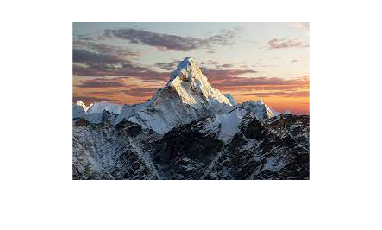

% display unfiltered image
imshow(I)


IG = im2gray(I)

IG = 183×275 uint8 matrix
   139   140   140   141   142   143   144   144   143   143   143   144   144   145   145   145   143   143   143   144   144   145   145   145   148   148   148   149   149   150   150   150   152   152   152   153   153   154   154   154   154   154   155   155   156   156   156   157   156   156
   139   140   140   141   142   143   144   144   143   143   144   144   145   145   145   146   143   143   144   144   145   145   145   146   148   148   149   149   150   150   150   151   152   152   152   153   153   154   154   154   154   155   155   155   156   156   157   157   158   158
   140   140   141   142   143   144   144   145   144   144   144   144   145   145   146   146   144   144   144   145   145   146   146   146   149   149   149   149   150   150   151   151   152   152   153   153   154   154   154   155   155   155   155   156   156   157   157   157   160   160
   140   141   141   142   143   144   145   145   144   144   145   14

IGG = imbinarize(IG)

IGG = 183×275 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


SE = strel("diamond",16)

SE = strel is a diamond shaped structuring element with properties:

      Neighborhood: [33×33 logical]
    Dimensionality: 2



IE = imerode( IG , SE )

IE = 183×275 uint8 matrix
   125   125   125   126   130   125   121   121   114   116   120   125   126   127   128   129   129   134   134   135   137   140   142   143   143   143   143   143   143   139   128   117   111   105   105   105   105   105   105   105   105   100   100   100   100   100   100   100   100   100
   125   125   125   125   125   121   121   114   114   114   116   120   125   126   127   128   127   127   127   128   130   134   137   139   143   143   143   143   139   128   117   111   105   105   105   105   105   105   105   105   100   100   100   100   100   100   100   100   100   100
   119   119   122   125   121   121   114   114   114   114   114   116   120   125   126   127   117   119   123   126   128   130   130   129   135   135   135   136   128   117   111   105   105   105   105   105   105   105   105   100   100   100   100   100   100   100   100   100   100   100
   119   119   119   121   121   114   114   114   114   114   114   11

ID = imdilate( IE , SE )

ID = 183×275 uint8 matrix
   130   134   134   135   137   140   142   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   139   128   117   111   105
   130   130   134   134   135   137   140   142   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   139   128   117   111   105   105
   130   130   130   134   134   135   137   140   142   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   143   139   128   117   111   105   105   105
   130   130   130   130   134   134   135   137   140   142   143   14


IB = imbinarize(ID)

IB = 183×275 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

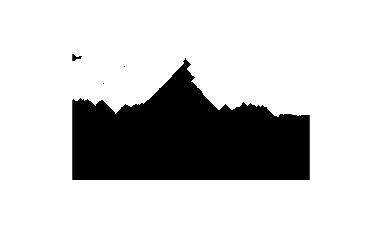




imshow(IB)

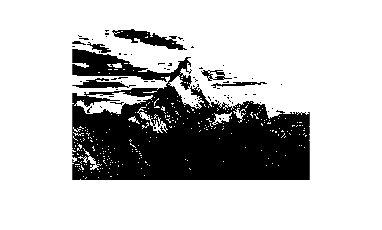

imshow(IGG)

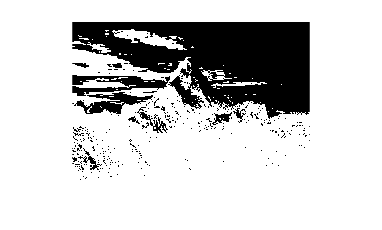


imshow(~IGG)

F = IGG - IB

F =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

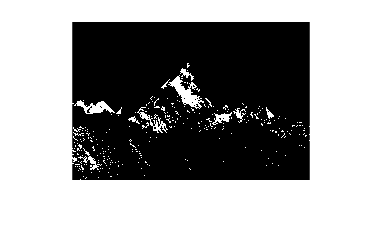


imshow(F)